**Adrian Cristian Crisan**

[https://drive.matlab.com/sharing/84572005-d72b-448a-a1c6-f336f4be1588](https://drive.matlab.com/sharing/84572005-d72b-448a-a1c6-f336f4be1588)

# Welding poses

A Unimation Puma 560 robot is used to weld a folded tubes frame as it is shown in the next figures.

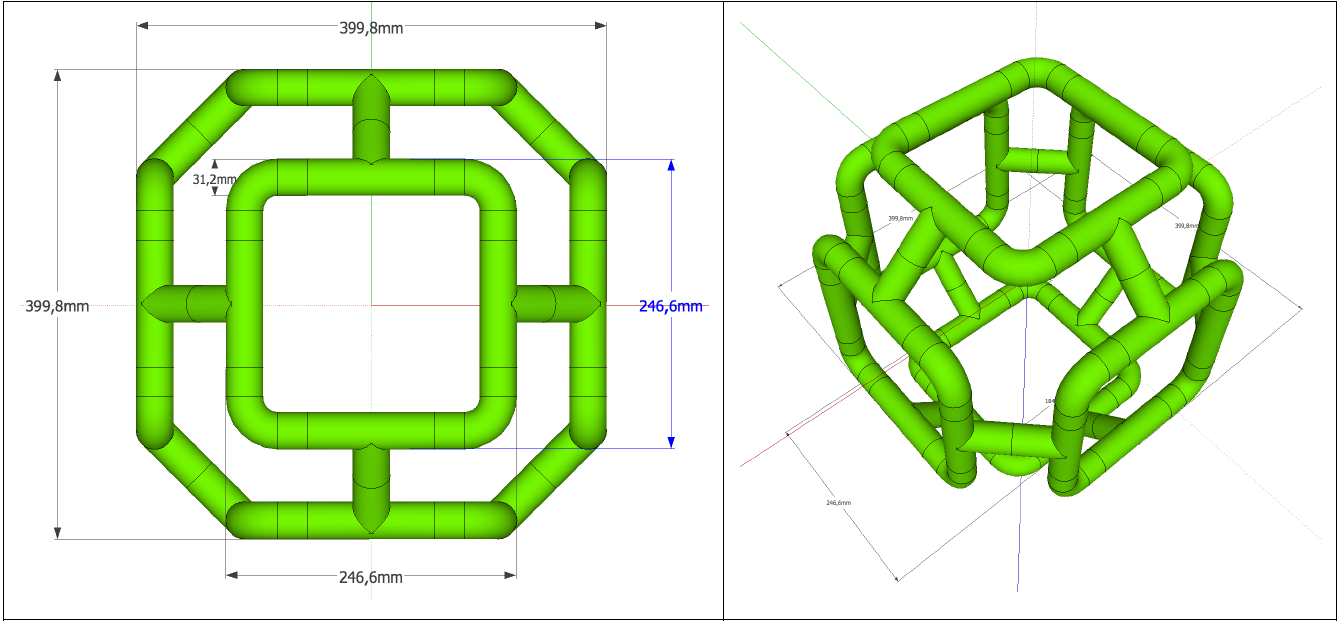

The task for the Puma 560 consists in welding the six folded squared tube among them with 32 points. The welding trajectory can be assumed to as two orthogonal and intersecting cylinders with radius 𝑟 = 15.6mm. The trajectory to be followed by the welder can be parameterized as follows:


$$p(t) = \left[ {\begin{array}{*{20}{c}}
  {x(t)} \\ 
  {y(t)} \\ 
  {z(t)} 
\end{array}} \right] = \left[ {\begin{array}{*{20}{c}}
  {r\cos (t)} \\ 
  {r\sin (t)} \\ 
  {\left[\kern-0.15em\left[ {r\cos (t)} 
 \right]\kern-0.15em\right]} 
\end{array}} \right];t \in \left[ {\begin{array}{*{20}{c}}
  0&{2\pi } 
\end{array}} \right]$$


## Read and plot the part

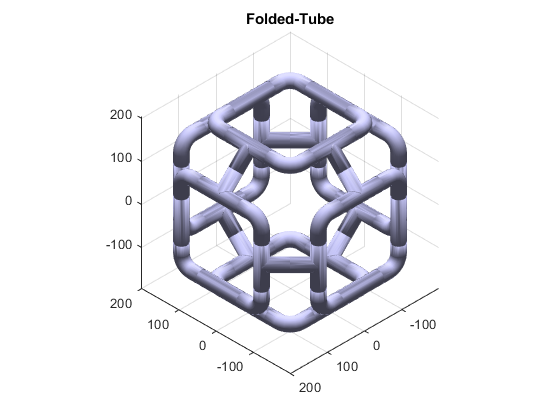

clear
[V,F, N,name]=stlRead('Folded_Tubes.stl');
clf
stlPlot(V,F,name)
axis equal
hold on

## Setting up dimensions

r=15.6; % Tube radius
t=0:pi/16:2*pi; % Scan variable
cp0=[r*cos(t);r*sin(t);abs(r*cos(t));ones(1,length(t))]% dot height

cp0 =    15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000   -3.0434   -5.9699   -8.6669  -11.0309  -12.9709  -14.4125  -15.3003  -15.6000  -15.3003  -14.4125  -12.9709  -11.0309   -8.6669   -5.9699   -3.0434   -0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000
         0    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000   -3.0434   -5.9699   -8.6669  -11.0309  -12.9709  -14.4125  -15.3003  -15.6000  -15.3003  -14.4125  -12.9709  -11.0309   -8.6669   -5.9699   -3.0434   -0.0000
   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000
 

## Plotting the welding points at origen

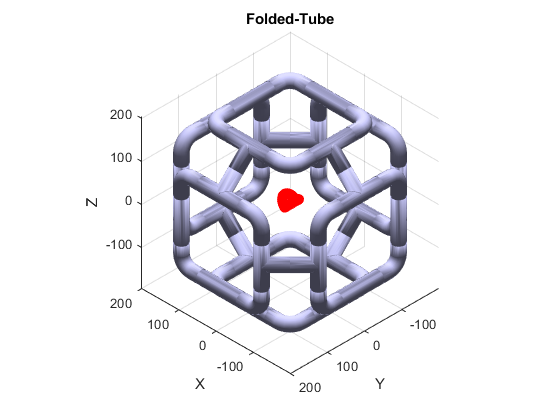

scatter3(cp0(1,:),cp0(2,:),cp0(3,:),'r','LineWidth',2)
xyzlabel% RTB

### Obtain the weld point coordinates of two tubes

Get familiar with the following RTB functions:

help on: transl, trotx, troty, trotz

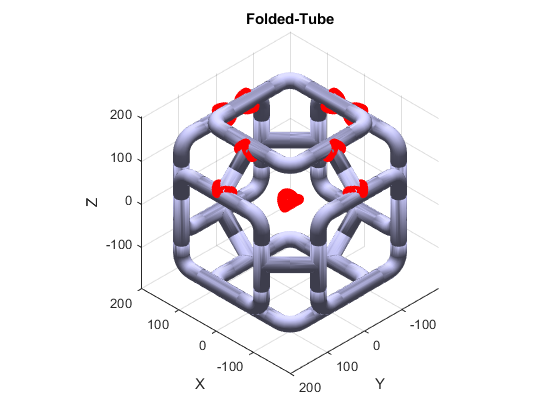

% First welding
TA_0 = transl(0.181887, 109.382, 188.585) * trotx(-135, 'deg');
cpA = TA_0 * cp0;

% Second welding
TB_0 = transl(0.181887, -106.906, 188.585) * trotx(135, 'deg');
TB_A = TB_0 * inv(TA_0);
cpB = TB_A * cpA;

% Third welding
TC_0 = transl(-107.962, 1.23804, 188.585) * trotz(90, 'deg') * trotx(-135, 'deg');
TC_A = TC_0 * inv(TA_0);
cpC = TC_A * cpA;

% Fourth welding
TD_0 = transl(108.326, 1.23, 188.585) * trotz(90, 'deg') * trotx(135, 'deg');
TD_A = TD_0 * inv(TA_0);
cpD = TD_A * cpA;

scatter3(cpA(1,:),cpA(2,:),cpA(3,:),'r','LineWidth', 2)
scatter3(cpB(1,:),cpB(2,:),cpB(3,:),'r','LineWidth', 2)
scatter3(cpC(1,:),cpC(2,:),cpC(3,:),'r','LineWidth', 2)
scatter3(cpD(1,:),cpD(2,:),cpD(3,:),'r','LineWidth', 2)

%% Second flor
% First welding
TE_0 = transl(0.181887, 185.715, 112.253) * trotx(45, 'deg');
cpE = TE_0 * cp0;

% Second welding
TF_0 = transl(0.181887, -183.238, 112.253) * trotx(-45, 'deg');
TF_E = TF_0 * inv(TE_0);
cpF = TF_E * cpE;

% Third welding
TG_0 = transl(-184.295, 1.23804, 112.253) * trotz(90, 'deg') * trotx(45, 'deg');
TG_E = TG_0 * inv(TE_0);
cpG = TG_E * cpE;

% Fourth welding
TH_0 = transl(184.658, 1.23, 112.253) * trotz(90, 'deg') * trotx(-45, 'deg');
TH_E = TH_0 * inv(TE_0);
cpH = TH_E * cpE;

scatter3(cpE(1,:),cpE(2,:),cpE(3,:),'r','LineWidth', 2)
scatter3(cpF(1,:),cpF(2,:),cpF(3,:),'r','LineWidth', 2)
scatter3(cpG(1,:),cpG(2,:),cpG(3,:),'r','LineWidth', 2)
scatter3(cpH(1,:),cpH(2,:),cpH(3,:),'r','LineWidth', 2)
xyzlabel% RTB

tube1 = [cpA, cpE]

tube1 =    15.7819   15.4821   14.5944   13.1528   11.2128    8.8488    6.1517    3.2253    0.1819   -2.8615   -5.7880   -8.4850  -10.8490  -12.7890  -14.2306  -15.1184  -15.4181  -15.1184  -14.2306  -12.7890  -10.8490   -8.4850   -5.7880   -2.8615    0.1819    3.2253    6.1517    8.8488   11.2128   13.1528   14.5944   15.4821   15.7819   15.7819   15.4821   14.5944   13.1528   11.2128    8.8488    6.1517    3.2253    0.1819   -2.8615   -5.7880   -8.4850  -10.8490  -12.7890  -14.2306  -15.1184  -15.4181
  120.4129  118.0489  115.3519  112.4254  109.3820  106.3386  103.4121  100.7151   98.3511  100.7151  103.4121  106.3386  109.3820  112.4254  115.3519  118.0489  120.4129  122.3529  123.7945  124.6823  124.9820  124.6823  123.7945  122.3529  120.4129  122.3529  123.7945  124.6823  124.9820  124.6823  123.7945  122.3529  120.4129  174.6841  177.0481  179.7451  182.6716  185.7150  188.7584  191.6849  194.3819  196.7459  194.3819  191.6849  188.7584  185.7150  182.6716  179.7451  177.0481 

tube2 = [cpB, cpF]

tube2 =    15.7819   15.4821   14.5944   13.1528   11.2128    8.8488    6.1517    3.2253    0.1819   -2.8615   -5.7880   -8.4850  -10.8490  -12.7890  -14.2306  -15.1184  -15.4181  -15.1184  -14.2306  -12.7890  -10.8490   -8.4850   -5.7880   -2.8615    0.1819    3.2253    6.1517    8.8488   11.2128   13.1528   14.5944   15.4821   15.7819   15.7819   15.4821   14.5944   13.1528   11.2128    8.8488    6.1517    3.2253    0.1819   -2.8615   -5.7880   -8.4850  -10.8490  -12.7890  -14.2306  -15.1184  -15.4181
 -117.9369 -119.8769 -121.3185 -122.2063 -122.5060 -122.2063 -121.3185 -119.8769 -117.9369 -119.8769 -121.3185 -122.2063 -122.5060 -122.2063 -121.3185 -119.8769 -117.9369 -115.5729 -112.8759 -109.9494 -106.9060 -103.8626 -100.9361  -98.2391  -95.8751  -98.2391 -100.9361 -103.8626 -106.9060 -109.9494 -112.8759 -115.5729 -117.9369 -172.2071 -170.2671 -168.8255 -167.9377 -167.6380 -167.9377 -168.8255 -170.2671 -172.2071 -170.2671 -168.8255 -167.9377 -167.6380 -167.9377 -168.8255 -170.2671 

## All weldding points in a vector

Obtain a vector with weldding points of the six folded squared 

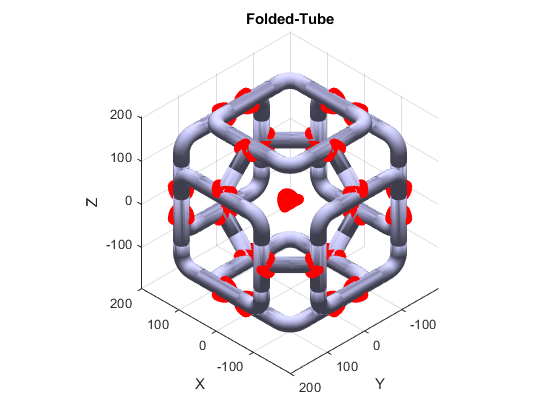

% Translate (I don't know why it is not symmetrical) and rotate the top (done above).
upper = [cpA, cpB, cpC, cpD, cpE, cpF, cpG, cpH];
T_lower = transl(0, 2.46804, 8.217) * trotx(180, 'deg');
lower = T_lower * upper;

scatter3(lower(1,:),lower(2,:),lower(3,:),'r','LineWidth', 2)

% Weld the x positive lateral part
TI_0 = transl(108.326, 185.715, 4.10875) * troty(90, 'deg') * trotx(45, 'deg');
cpI = TI_0 * cp0;

TJ_0 = transl(108.326, -183.238, 4.10875) * troty(90, 'deg') * trotx(-45, 'deg');
cpJ = TJ_0 * cp0;

TK_0 = transl(184.658, 109.382, 4.10875) * troty(90, 'deg') * trotx(-135, 'deg');
cpK = TK_0 * cp0;

TL_0 = transl(184.658, -106.906, 4.10875) * troty(90, 'deg') * trotx(135, 'deg');
cpL = TL_0 * cp0;

scatter3(cpI(1,:),cpI(2,:),cpI(3,:),'r','LineWidth', 2)
scatter3(cpJ(1,:),cpJ(2,:),cpJ(3,:),'r','LineWidth', 2)
scatter3(cpK(1,:),cpK(2,:),cpK(3,:),'r','LineWidth', 2)
scatter3(cpL(1,:),cpL(2,:),cpL(3,:),'r','LineWidth', 2)

% Weld the x negative lateral part doing a translation and a rotation

lateral = [cpI, cpJ, cpK, cpL];
T_lateral = transl(0.363, 0, 8.2175) * troty(180, 'deg');
lateral2 = T_lateral * lateral;

scatter3(lateral2(1,:),lateral2(2,:),lateral2(3,:),'r','LineWidth', 2)
hold off

[V,F, N,name]=stlRead('Folded_Tubes.stl');
clf
stlPlot(V,F,name)
axis equal
hold on

welddings = [upper, lower, lateral, lateral2]

welddings =    15.7819   15.4821   14.5944   13.1528   11.2128    8.8488    6.1517    3.2253    0.1819   -2.8615   -5.7880   -8.4850  -10.8490  -12.7890  -14.2306  -15.1184  -15.4181  -15.1184  -14.2306  -12.7890  -10.8490   -8.4850   -5.7880   -2.8615    0.1819    3.2253    6.1517    8.8488   11.2128   13.1528   14.5944   15.4821   15.7819   15.7819   15.4821   14.5944   13.1528   11.2128    8.8488    6.1517    3.2253    0.1819   -2.8615   -5.7880   -8.4850  -10.8490  -12.7890  -14.2306  -15.1184  -15.4181
  120.4129  118.0489  115.3519  112.4254  109.3820  106.3386  103.4121  100.7151   98.3511  100.7151  103.4121  106.3386  109.3820  112.4254  115.3519  118.0489  120.4129  122.3529  123.7945  124.6823  124.9820  124.6823  123.7945  122.3529  120.4129  122.3529  123.7945  124.6823  124.9820  124.6823  123.7945  122.3529  120.4129 -117.9369 -119.8769 -121.3185 -122.2063 -122.5060 -122.2063 -121.3185 -119.8769 -117.9369 -119.8769 -121.3185 -122.2063 -122.5060 -122.2063 -121.3185 -119.8

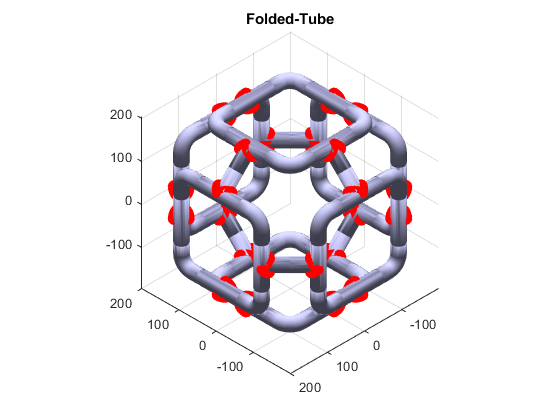


scatter3(welddings(1,:),welddings(2,:),welddings(3,:),'r','LineWidth', 2)